clear
set(0,'defaultAxesTickLabelInterpreter','latex');
set(0,'defaultTextInterpreter','latex'); set(0,'defaultLegendInterpreter','latex');
MTOW = 30000 * 9.81;
WS = 3332;
srefref = MTOW/WS

srefref = 88.3253


AR = 10;
Sweep = 0;
Taper = 0.79;
Sref = srefref;
discret = 0.001

discret = 1.0000e-03


fuselage_rad = 1.15;
%% discritize planform to plot
[c_y,span_disc,quarterchord,c_bar,span] = planformcalc(AR, Sweep, Taper, Sref, discret) 

c_y =     3.3206    3.3206    3.3205    3.3205    3.3204    3.3204    3.3203    3.3203    3.3202    3.3202    3.3202    3.3201    3.3201    3.3200    3.3200    3.3199    3.3199    3.3198    3.3198    3.3197    3.3197    3.3196    3.3196    3.3195    3.3195    3.3195    3.3194    3.3194    3.3193    3.3193    3.3192    3.3192    3.3191    3.3191    3.3190    3.3190    3.3189    3.3189    3.3188    3.3188    3.3187    3.3187    3.3187    3.3186    3.3186    3.3185    3.3185    3.3184    3.3184    3.3183


span_disc =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


quarterchord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


c_bar = 2.9720

span = 29.7196

MACpos = 1

MACpos = 1

semispan = length(span_disc)*0.01

semispan = 148.6000

longitudinalMACac =  6;
fuselagedatum = 0

fuselagedatum = 0

feselageend = 15

feselageend = 15


[~, fuseidx] = min(abs(span_disc - fuselage_rad))

fuseidx = 1151

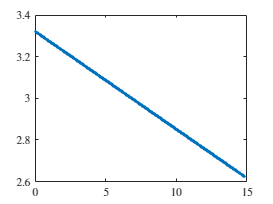



plot(span_disc,c_y,'.')
% x_engine = quarterchord(ceil(length(c_y)*0.37))
% height_engine0.37*max(span_disc)*tand(5)-0.175*c_y(ceil(length(c_y)*0.37))-0.9
LEsweep = (quarterchord-quarterchord(MACpos) + longitudinalMACac) - 0.25 .* c_y;
TEsweep = (quarterchord-quarterchord(MACpos) + longitudinalMACac) + 0.75 .* c_y;
quarterchordplot = (quarterchord-quarterchord(MACpos) + longitudinalMACac);
%origin at quarterchord point of root chord

hold off

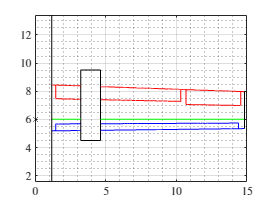

Flap(1).start = 0.3 + fuselage_rad;
Flap(1).end = 2.075 + fuselage_rad;
Flap(1).chordrat = 0.3;
Flap(1).c_y = [span_disc(span_disc >= Flap(1).start & span_disc <= Flap(1).end);TEsweep(span_disc >= Flap(1).start & span_disc <= Flap(1).end) - Flap(1).chordrat.*c_y(span_disc >= Flap(1).start & span_disc <= Flap(1).end)];
[~, Flap(1).edgeinidx] = min(abs(span_disc - Flap(1).start));
[~, Flap(1).edgeoutidx] = min(abs(span_disc - Flap(1).end));
Flap(1).edgein = [Flap(1).start.*ones(1,10);linspace(TEsweep(Flap(1).edgeinidx),Flap(1).c_y(2,1),10)];
Flap(1).edgeout = [Flap(1).end.*ones(1,10);linspace(TEsweep(Flap(1).edgeoutidx),Flap(1).c_y(end),10)];

plot (Flap(1).c_y(1,:),Flap(1).c_y(2,:),'r')
hold on
plot (Flap(1).edgein(1,:), Flap(1).edgein(2,:), 'r')
plot (Flap(1).edgeout(1,:), Flap(1).edgeout(2,:), 'r')

plot (-Flap(1).c_y(1,:),Flap(1).c_y(2,:),'r')
hold on
plot (-Flap(1).edgein(1,:), Flap(1).edgein(2,:), 'r')
plot (-Flap(1).edgeout(1,:), Flap(1).edgeout(2,:), 'r')



Flap(2).start = 3.475+ fuselage_rad;
Flap(2).end = 9.167+ fuselage_rad;
Flap(2).chordrat = 0.3;
Flap(2).c_y = [span_disc(span_disc >= Flap(2).start & span_disc <= Flap(2).end);TEsweep(span_disc >= Flap(2).start & span_disc <= Flap(2).end) - Flap(2).chordrat.*c_y(span_disc >= Flap(2).start & span_disc <= Flap(2).end)];
[~, Flap(2).edgeinidx] = min(abs(span_disc - Flap(2).start));
[~, Flap(2).edgeoutidx] = min(abs(span_disc - Flap(2).end));
Flap(2).edgein = [Flap(2).start.*ones(1,10);linspace(TEsweep(Flap(2).edgeinidx),Flap(2).c_y(2,1),10)];
Flap(2).edgeout = [Flap(2).end .*ones(1,10);linspace(TEsweep(Flap(2).edgeoutidx),Flap(2).c_y(end),10)];

plot (Flap(2).c_y(1,:),Flap(2).c_y(2,:),'r')
plot (Flap(2).edgein(1,:), Flap(2).edgein(2,:), 'r')
plot (Flap(2).edgeout(1,:), Flap(2).edgeout(2,:), 'r')

plot (-Flap(2).c_y(1,:),Flap(2).c_y(2,:),'r')
plot (-Flap(2).edgein(1,:), Flap(2).edgein(2,:), 'r')
plot (-Flap(2).edgeout(1,:), Flap(2).edgeout(2,:), 'r')


Slat(1).start = 0.3 + fuselage_rad;
Slat(1).end = 2.075 + fuselage_rad;
Slat(1).chordrat = 0.15;
Slat(1).c_y = [span_disc(span_disc >= Slat(1).start & span_disc <= Slat(1).end );LEsweep(span_disc >= Slat(1).start & span_disc <= Slat(1).end) + Slat(1).chordrat.*c_y(span_disc >= Slat(1).start & span_disc <= Slat(1).end )];
[~, Slat(1).edgeinidx] = min(abs(span_disc - Slat(1).start));
[~, Slat(1).edgeoutidx] = min(abs(span_disc - Slat(1).end));
Slat(1).edgein = [Slat(1).start.*ones(1,10);linspace(LEsweep(Slat(1).edgeinidx),Slat(1).c_y(2,1),10)];
Slat(1).edgeout = [Slat(1).end .*ones(1,10);linspace(LEsweep(Slat(1).edgeoutidx),Slat(1).c_y(end),10)];

plot (Slat(1).c_y(1,:),Slat(1).c_y(2,:),'b')
plot (Slat(1).edgein(1,:), Slat(1).edgein(2,:), 'b')
plot (Slat(1).edgeout(1,:), Slat(1).edgeout(2,:), 'b')

plot (-Slat(1).c_y(1,:),Slat(1).c_y(2,:),'b')
plot (-Slat(1).edgein(1,:), Slat(1).edgein(2,:), 'b')
plot (-Slat(1).edgeout(1,:), Slat(1).edgeout(2,:), 'b')

Slat(2).start = 3.475+ fuselage_rad;
Slat(2).end = 13.275+ fuselage_rad;
Slat(2).chordrat = 0.15;
Slat(2).c_y = [span_disc(span_disc >= Slat(2).start & span_disc <= Slat(2).end );LEsweep(span_disc >= Slat(2).start & span_disc <= Slat(2).end) + Slat(2).chordrat.*c_y(span_disc >= Slat(2).start & span_disc <= Slat(2).end )];
[~, Slat(2).edgeinidx] = min(abs(span_disc - Slat(2).start));
[~, Slat(2).edgeoutidx] = min(abs(span_disc - Slat(2).end));
Slat(2).edgein = [Slat(2).start.*ones(1,10);linspace(LEsweep(Slat(2).edgeinidx),Slat(2).c_y(2,1),10)];
Slat(2).edgeout = [Slat(2).end .*ones(1,10);linspace(LEsweep(Slat(2).edgeoutidx),Slat(2).c_y(end),10)];

plot (Slat(2).c_y(1,:),Slat(2).c_y(2,:),'b')
plot (Slat(2).edgein(1,:), Slat(2).edgein(2,:), 'b')
plot (Slat(2).edgeout(1,:), Slat(2).edgeout(2,:), 'b')

plot (-Slat(2).c_y(1,:),Slat(2).c_y(2,:),'b')
plot (-Slat(2).edgein(1,:), Slat(2).edgein(2,:), 'b')
plot (-Slat(2).edgeout(1,:), Slat(2).edgeout(2,:), 'b')


Aileron.start = 10.69;
Aileron.end = 14.59;
Aileron.chordrat = 0.376;
Aileron.c_y = [span_disc(span_disc >= Aileron.start & span_disc <= Aileron.end );TEsweep(span_disc >= Aileron.start & span_disc <= Aileron.end) - Aileron.chordrat.*c_y(span_disc >= Aileron.start & span_disc <= Aileron.end)];
[~, Aileron.edgeinidx] = min(abs(span_disc - Aileron.start));
[~, Aileron.edgeoutidx] = min(abs(span_disc - Aileron.end));
Aileron.edgein = [Aileron.start.*ones(1,10);linspace(TEsweep(Aileron.edgeinidx),Aileron.c_y(2,1),10)];
Aileron.edgeout = [Aileron.end .*ones(1,10);linspace(TEsweep(Aileron.edgeoutidx),Aileron.c_y(end),10)];

plot (Aileron.c_y(1,:),Aileron.c_y(2,:),'r')
plot (Aileron.edgein(1,:), Aileron.edgein(2,:), 'r')
plot (Aileron.edgeout(1,:), Aileron.edgeout(2,:), 'r')

plot (-Aileron.c_y(1,:),Aileron.c_y(2,:),'r')
plot (-Aileron.edgein(1,:), Aileron.edgein(2,:), 'r')
plot (-Aileron.edgeout(1,:), Aileron.edgeout(2,:), 'r')



Nacelle. start = Flap(1).end;
Nacelle. end = Flap(2).start;
Nacelle. length = 5;
Nacelle. pos = 7;
Nacelle.frontedge = [span_disc(span_disc >= Nacelle. start & span_disc <= Nacelle. end ); (Nacelle. pos - Nacelle. length/2)*ones(1,size(span_disc(span_disc >= Nacelle. start & span_disc <= Nacelle. end),2)) ];
Nacelle.rearedge = [span_disc(span_disc >= Nacelle. start & span_disc <= Nacelle. end ); (Nacelle. pos + Nacelle. length/2)*ones(1,size(span_disc(span_disc >= Nacelle. start & span_disc <= Nacelle. end),2)) ];
Nacelle.edgein = [Nacelle.start.*ones(1,10);linspace(Nacelle.frontedge(2,1),Nacelle.rearedge(2,1),10)];
Nacelle.edgeout = [Nacelle.end .*ones(1,10);linspace(Nacelle.frontedge(2,1),Nacelle.rearedge(2,1),10)];


plot (Nacelle.frontedge(1,:),Nacelle.frontedge(2,:),'k')
plot (Nacelle.rearedge(1,:), Nacelle.rearedge(2,:), 'k')
plot (Nacelle.edgein (1,:),Nacelle.edgein (2,:),'k')
plot (Nacelle.edgeout (1,:), Nacelle.edgeout (2,:), 'k')

plot (-Nacelle.frontedge(1,:),Nacelle.frontedge(2,:),'k')
plot (-Nacelle.rearedge(1,:), Nacelle.rearedge(2,:), 'k')
plot (-Nacelle.edgein (1,:),Nacelle.edgein (2,:),'k')
plot (-Nacelle.edgeout (1,:), Nacelle.edgeout (2,:), 'k')


plot (span_disc(span_disc >= fuselage_rad & span_disc <= Nacelle. start),LEsweep(span_disc >= fuselage_rad & span_disc <= Nacelle. start),'b')
plot (span_disc(span_disc >= Nacelle. end),LEsweep(span_disc >= Nacelle. end),'b')
hold on
plot (span_disc(span_disc >= fuselage_rad & span_disc <= Nacelle. start),TEsweep(span_disc >= fuselage_rad & span_disc <= Nacelle. start),'r')
plot (span_disc(span_disc >= Nacelle. end),TEsweep(span_disc >= Nacelle. end),'r')

plot (span_disc(span_disc >= fuselage_rad & span_disc <= Nacelle. start),quarterchordplot(span_disc >= fuselage_rad & span_disc <= Nacelle. start),'g')
plot (span_disc(span_disc >= Nacelle. end),quarterchordplot(span_disc >= Nacelle. end),'g')
plot (span_disc(MACpos),quarterchordplot(MACpos),'xk')

plot(-span_disc(span_disc >= fuselage_rad & span_disc <= Nacelle.start), LEsweep(span_disc >= fuselage_rad & span_disc <= Nacelle.start), 'b');
plot(-span_disc(span_disc >= Nacelle.end), LEsweep(span_disc >= Nacelle.end), 'b');
plot(-span_disc(span_disc >= fuselage_rad & span_disc <= Nacelle.start), TEsweep(span_disc >= fuselage_rad & span_disc <= Nacelle.start), 'r');
plot(-span_disc(span_disc >= Nacelle.end), TEsweep(span_disc >= Nacelle.end), 'r');
plot(-span_disc(span_disc >= fuselage_rad & span_disc <= Nacelle.start), quarterchordplot(span_disc >= fuselage_rad & span_disc <= Nacelle.start), 'g');
plot(-span_disc(span_disc >= Nacelle.end), quarterchordplot(span_disc >= Nacelle.end), 'g');
plot(-span_disc(MACpos), quarterchordplot(MACpos), 'xk');


plot ([span_disc(fuseidx),span_disc(fuseidx)], [LEsweep(fuseidx),TEsweep(fuseidx)],'k')
plot ([span_disc(end),span_disc(end)], [LEsweep(end),TEsweep(end)],'k')
plot ([-span_disc(fuseidx),-span_disc(fuseidx)], [LEsweep(fuseidx),TEsweep(fuseidx)],'k')
plot ([-span_disc(end),-span_disc(end)], [LEsweep(end),TEsweep(end)],'k')

plot ([span_disc(fuseidx),span_disc(fuseidx)],[fuselagedatum,feselageend],'k')
plot ([-span_disc(fuseidx),-span_disc(fuseidx)],[fuselagedatum,feselageend],'k')
plot ([-span_disc(fuseidx),span_disc(fuseidx)],[fuselagedatum,fuselagedatum],'k')
plot ([-span_disc(fuseidx),span_disc(fuseidx)],[feselageend,feselageend],'k')






axis equal
xlim([0 15])
hold off
grid on
grid minor

chordpos = 0;
[Sweep_c] = sweepcalc(LEsweep,chordpos,c_y,span_disc)

Sweep_c = 0.6722


% Cl_alpha = 6.68
% Mach = 0.45
% S_rat = (Sref-2*fuselage_rad*c_y(fuselage_rad*100))/Sref
% FLF = 1.07*(1+2*fuselage_rad/semispan*2)^2
% yetaest = 0;
% CL_alpha_curve = easyCLcurve(Cl_alpha, Mach, Sweep, AR, S_rat, FLF,yetaest)



function [c_y,span_disc,quarterchord,c_bar,span] = planformcalc(AR, Sweep, Taper, Sref, discret) 
%(AR, Sweep, Taper, c_bar) 
span = sqrt(AR * Sref);
c_bar = Sref/span;
span_disc = [0:discret:span/2];
syms croot;
eqn = (croot+Taper*croot)*(span/2) == Sref;
croot = double(solve(eqn,croot));
c_y =  (Taper-1)*croot/(span/2).*span_disc + croot;
quarterchord =  span_disc .* tand(Sweep);

end

function [Sweep_c] = sweepcalc(LEsweep,chordpos,c_y,span_disc)
sweeppos = LEsweep + chordpos .* c_y;
Sweep_c = atand((sweeppos(end)-sweeppos(1))/(span_disc(end)-span_disc(1)));
end

function [CL_alpha_curve] = easyCLcurve(Cl_alpha, Mach, Sweep, AR, S_rat, FLF,yetaest)
beta = (1-Mach^2)^0.5;
if yetaest == 0
    yeta = Cl_alpha/(2*pi/beta);
else
    yeta = yetaest;
end
CL_alpha_curve = 2*pi*AR/(2+(4+((AR^2*beta^2)/(yeta^2))*(1+(tand(Sweep))^2/(beta^2)))^0.5) * S_rat * FLF;
end

function [Re] = easyreynolds1(height,refl,machnum,velo)
[T,a,p,rho] = atmosisa(height);
if machnum == 0
    mu = 2.791*10^(-7) * T ^(0.7355);
    Re = rho * refl * velo / (mu);
elseif machnum ~= 0
    mu = 2.791*10^(-7) * T ^(0.7355);
    Re = rho * machnum * refl * a / (mu);
end
end